%% Problem 3: Resampling with resample.m and interp1.m
clear; clc; close all;

% Robust input-file search for Live Script / temp execution paths.
fileName = 'mhint_01_01.wav';
labFixedDir = '/Users/hwy/Desktop/个人/26春/语音信号处理/lab1';

candidateDirs = {};
candidateDirs{end+1} = pwd;

try
    mPath = fileparts(mfilename('fullpath'));
    if ~isempty(mPath)
        candidateDirs{end+1} = mPath;
    end
catch
end

sPath = which('problem3_solution.m');
if ~isempty(sPath)
    candidateDirs{end+1} = fileparts(sPath);
end

candidateDirs{end+1} = labFixedDir;

inFile = '';
for i = 1:numel(candidateDirs)
    cFile = fullfile(candidateDirs{i}, fileName);
    if isfile(cFile)
        inFile = cFile;
        break;
    end
end

if isempty(inFile)
    error(['Cannot find ', fileName, '. Please set MATLAB Current Folder to:\n', ...
           labFixedDir]);
end

workDir = fileparts(inFile);
fprintf('Using input file: %s\n', inFile);

Using input file: /Users/hwy/Desktop/个人/26春/语音信号处理/lab1/mhint_01_01.wav



[x, fs] = audioread(inFile);
if size(x, 2) > 1
    x = mean(x, 2);
end
x = x(:);

targetFs = [20000, 8000];

fprintf('Original sampling rate: %d Hz\n', fs);

Original sampling rate: 16000 Hz


fprintf('Original samples: %d, duration: %.3f s\n', numel(x), numel(x) / fs);

Original samples: 59670, duration: 3.729 s



%% Method A: resample.m
yRes = cell(size(targetFs));
for k = 1:numel(targetFs)
    [p, q] = rat(targetFs(k) / fs, 1e-12);
    yRes{k} = resample(x, p, q);
    fprintf('resample -> %5d Hz: samples = %d, duration = %.3f s\n', ...
        targetFs(k), numel(yRes{k}), numel(yRes{k}) / targetFs(k));
end

resample -> 20000 Hz: samples = 74588, duration = 3.729 s
resample ->  8000 Hz: samples = 29835, duration = 3.729 s



%% Method B: interp1.m
t = (0:numel(x) - 1)' / fs;
yInterp = cell(size(targetFs));
for k = 1:numel(targetFs)
    tNew = (0 : 1/targetFs(k) : t(end))';
    yInterp{k} = interp1(t, x, tNew, 'linear');
    yInterp{k}(isnan(yInterp{k})) = 0;
    fprintf('interp1  -> %5d Hz: samples = %d, duration = %.3f s\n', ...
        targetFs(k), numel(yInterp{k}), numel(yInterp{k}) / targetFs(k));
end

interp1  -> 20000 Hz: samples = 74587, duration = 3.729 s
interp1  ->  8000 Hz: samples = 29835, duration = 3.729 s


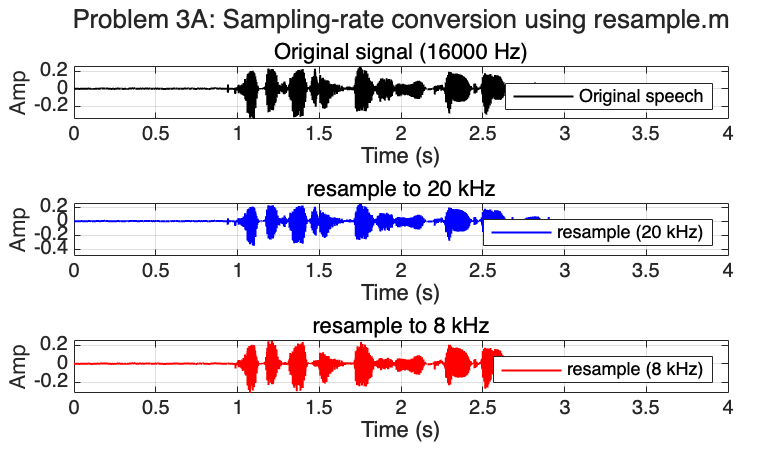


%% Plot waveforms for resample.m (keep original figure)
figure('Name', 'Problem 3 - resample.m', 'Color', 'w', 'Position', [80 80 1200 700]);
tiledlayout(3, 1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
h0 = plot((0:numel(x)-1)/fs, x, 'k', 'LineWidth', 1); grid on;
title(sprintf('Original signal (%d Hz)', fs));
xlabel('Time (s)'); ylabel('Amp');
legend(h0, 'Original speech', 'Location', 'northeast');

nexttile;
h1 = plot((0:numel(yRes{1})-1)/targetFs(1), yRes{1}, 'b', 'LineWidth', 1); grid on;
title('resample to 20 kHz');
xlabel('Time (s)'); ylabel('Amp');
legend(h1, 'resample (20 kHz)', 'Location', 'northeast');

nexttile;
h2 = plot((0:numel(yRes{2})-1)/targetFs(2), yRes{2}, 'r', 'LineWidth', 1); grid on;
title('resample to 8 kHz');
xlabel('Time (s)'); ylabel('Amp');
legend(h2, 'resample (8 kHz)', 'Location', 'northeast');

if exist('sgtitle', 'file') == 2
    sgtitle('Problem 3A: Sampling-rate conversion using resample.m');
end

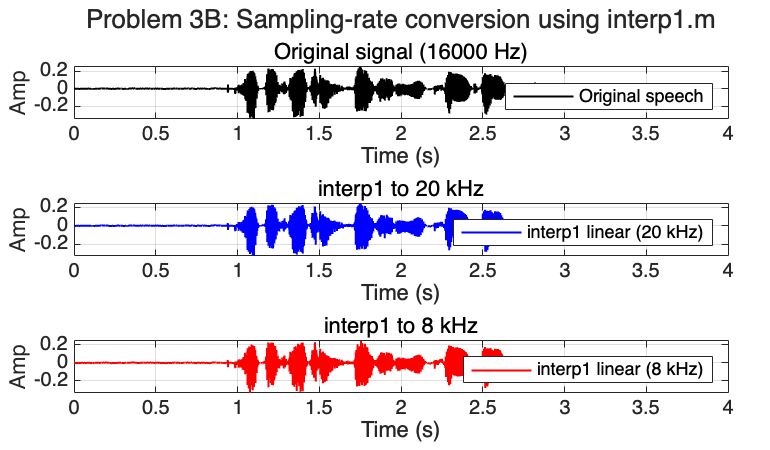


%% Plot waveforms for interp1.m (keep original figure)
figure('Name', 'Problem 3 - interp1.m', 'Color', 'w', 'Position', [140 120 1200 700]);
tiledlayout(3, 1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
h3 = plot((0:numel(x)-1)/fs, x, 'k', 'LineWidth', 1); grid on;
title(sprintf('Original signal (%d Hz)', fs));
xlabel('Time (s)'); ylabel('Amp');
legend(h3, 'Original speech', 'Location', 'northeast');

nexttile;
h4 = plot((0:numel(yInterp{1})-1)/targetFs(1), yInterp{1}, 'b', 'LineWidth', 1); grid on;
title('interp1 to 20 kHz');
xlabel('Time (s)'); ylabel('Amp');
legend(h4, 'interp1 linear (20 kHz)', 'Location', 'northeast');

nexttile;
h5 = plot((0:numel(yInterp{2})-1)/targetFs(2), yInterp{2}, 'r', 'LineWidth', 1); grid on;
title('interp1 to 8 kHz');
xlabel('Time (s)'); ylabel('Amp');
legend(h5, 'interp1 linear (8 kHz)', 'Location', 'northeast');

if exist('sgtitle', 'file') == 2
    sgtitle('Problem 3B: Sampling-rate conversion using interp1.m');
end

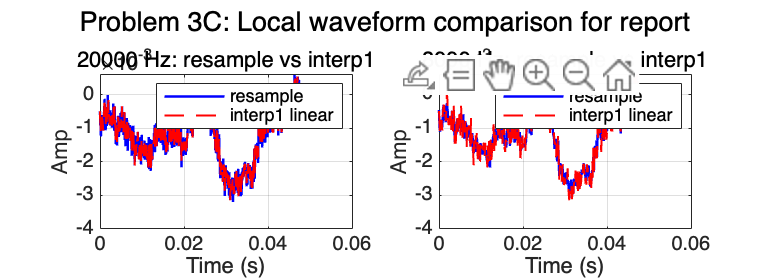


%% Existing local method comparison (keep original figure)
figure('Name', 'Problem 3 - method comparison (first 50 ms)', 'Color', 'w', 'Position', [220 180 1000 360]);
for k = 1:numel(targetFs)
    subplot(1, 2, k);
    nShow = min([numel(yRes{k}), numel(yInterp{k}), round(0.05 * targetFs(k))]);
    tt = (0:nShow-1) / targetFs(k);
    plot(tt, yRes{k}(1:nShow), 'b', 'LineWidth', 1.2); hold on;
    plot(tt, yInterp{k}(1:nShow), 'r--', 'LineWidth', 1.0); grid on;
    xlabel('Time (s)'); ylabel('Amp');
    title(sprintf('%d Hz: resample vs interp1', targetFs(k)));
    legend('resample', 'interp1 linear', 'Location', 'northeast');
end
if exist('sgtitle', 'file') == 2
    sgtitle('Problem 3C: Local waveform comparison for report');
end

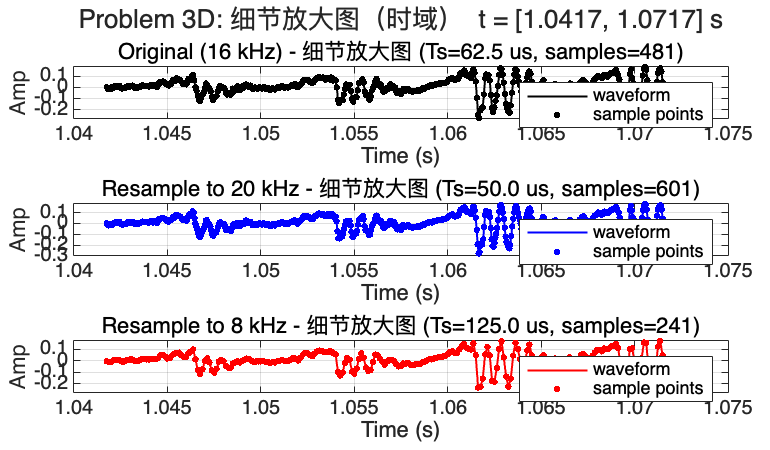


%% NEW: Clear-detail zoom (time domain) to show differences clearly
absX = abs(x);
idxActive = find(absX > 0.35 * max(absX), 1, 'first');
if isempty(idxActive)
    idxActive = round(1.2 * fs);
end
zoomDurSec = 0.03;  % 30 ms
idxStart = max(1, idxActive - round(0.005 * fs));
tStart = (idxStart - 1) / fs;
tEnd = min((numel(x)-1)/fs, tStart + zoomDurSec);

figure('Name', 'Problem 3D - 细节放大图（时域，resample）', 'Color', 'w', 'Position', [120 120 1200 700]);
tiledlayout(3, 1, 'Padding', 'compact', 'TileSpacing', 'compact');

sigSet = {x, yRes{1}, yRes{2}};
fsSet = [fs, targetFs(1), targetFs(2)];
colorSet = {'k', 'b', 'r'};
nameSet = {'Original (16 kHz)', 'Resample to 20 kHz', 'Resample to 8 kHz'};

for i = 1:3
    nexttile;
    xx = sigSet{i};
    ff = fsSet(i);
    tt = (0:numel(xx)-1) / ff;
    mask = tt >= tStart & tt <= min(tEnd, tt(end));
    tLocal = tt(mask);
    xLocal = xx(mask);

    plot(tLocal, xLocal, colorSet{i}, 'LineWidth', 1.0); hold on;
    plot(tLocal, xLocal, '.', 'Color', colorSet{i}, 'MarkerSize', 8);
    grid on;
    xlabel('Time (s)'); ylabel('Amp');
    title(sprintf('%s - 细节放大图 (Ts=%.1f us, samples=%d)', ...
        nameSet{i}, 1e6/ff, numel(xLocal)));
    legend('waveform', 'sample points', 'Location', 'northeast');
end
if exist('sgtitle', 'file') == 2
    sgtitle(sprintf('Problem 3D: 细节放大图（时域）  t = [%.4f, %.4f] s', tStart, tEnd));
end

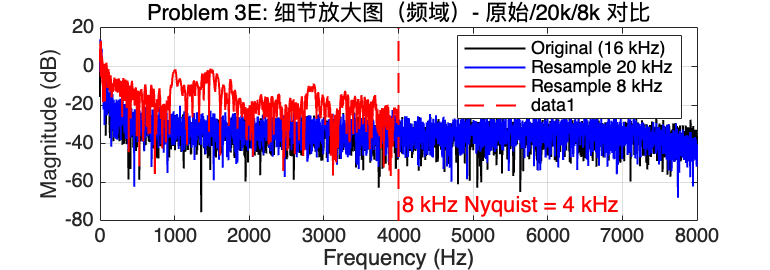


%% NEW: Clear-detail zoom (frequency domain) to show bandwidth differences
nfft = 8192;
X0 = fft(x, nfft);
X20 = fft(yRes{1}, nfft);
X8 = fft(yRes{2}, nfft);

f0 = (0:nfft/2) * fs / nfft;
f20 = (0:nfft/2) * targetFs(1) / nfft;
f8 = (0:nfft/2) * targetFs(2) / nfft;

m0 = 20 * log10(abs(X0(1:nfft/2+1)) + 1e-10);
m20 = 20 * log10(abs(X20(1:nfft/2+1)) + 1e-10);
m8 = 20 * log10(abs(X8(1:nfft/2+1)) + 1e-10);

figure('Name', 'Problem 3E - 细节放大图（频域）', 'Color', 'w', 'Position', [160 160 1200 420]);
plot(f0, m0, 'k', 'LineWidth', 1.0); hold on; grid on;
plot(f20, m20, 'b', 'LineWidth', 1.0);
plot(f8, m8, 'r', 'LineWidth', 1.0);
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
title('Problem 3E: 细节放大图（频域）- 原始/20k/8k 对比');
legend('Original (16 kHz)', 'Resample 20 kHz', 'Resample 8 kHz', 'Location', 'northeast');
xlim([0 8000]);

yL = ylim;
plot([4000 4000], yL, 'r--', 'LineWidth', 1.0);
text(4050, yL(1) + 0.08 * (yL(2)-yL(1)), '8 kHz Nyquist = 4 kHz', 'Color', 'r');


fprintf('\nProblem 3 done.\n');


Problem 3 done.


fprintf('Output directory context: %s\n', workDir);

Output directory context: /Users/hwy/Desktop/个人/26春/语音信号处理/lab1
